# **JACOBIAN MATRIX OF KUKA KR5 ARC**

## a) Find the Jacobian operator

In second homework DH Table parameters are calculated as follows

syms theta1 theta2 theta3 theta4 theta5 theta6;
theta=[theta1 theta2 theta3 theta4 theta5 theta6];%radian joint angle
% theta=[pi pi/2 0 0 0 0];%radian joint angle
a=[180 600 120 0 0 0]*0.001;%meter
alpha=[90 180 -90 90 -90 0];%degree
d=[400 0 0 620 0 115]*0.001;%meter

Each homogeneous transformation A is calculated corresponding to the formula below then, forward kinematic matrix T is obtained by multiplication of A matrices

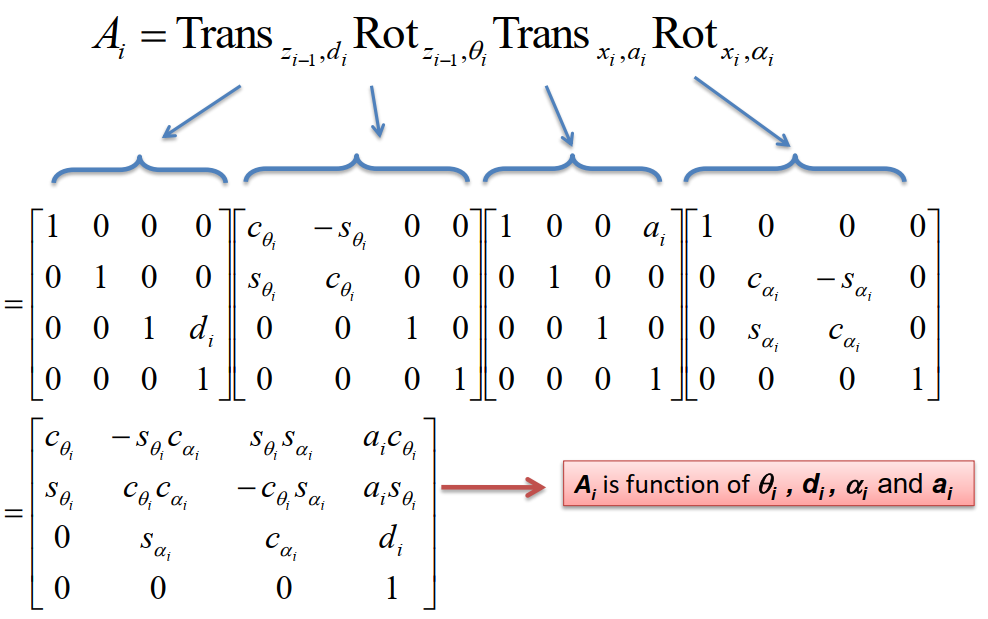

z=[];o=[];
T=eye(4);%identity matrix 
z=[z,[0;0;1]];%z_0=[0 0 1]
o=[o,[0;0;0]];%o_0=[0 0 0]
for i=1:6%6 DOF
    A=[cos(theta(i)), -sin(theta(i))*cosd(alpha(i)), ...
    sin(theta(i))*sind(alpha(i)), a(i)*cos(theta(i));...
    sin(theta(i)), cos(theta(i))*cosd(alpha(i)), ...
    -cos(theta(i))*sind(alpha(i)), a(i)*sin(theta(i));
    0, sind(alpha(i)), cosd(alpha(i)), d(i);
    0, 0, 0, 1];
    T=T*A
    z=[z,T(1:3,3)];%z_0 to z_6
    o=[o,T(1:3,4)];%o_0 to o_6
 
end

$$T = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & \sin\left(\theta_{1}\right) & \frac{9\,\cos\left(\theta_{1}\right)}{50}\\ \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & \frac{9\,\sin\left(\theta_{1}\right)}{50}\\ 0 & 1 & 0 & \frac{2}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\sin\left(\theta_{1}\right) & \frac{9\,\cos\left(\theta_{1}\right)}{50}+\frac{3\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)}{5}\\ \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{1}\right) & \frac{9\,\sin\left(\theta_{1}\right)}{50}+\frac{3\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)}{5}\\ \sin\left(\theta_{2}\right) & -\cos\left(\theta_{2}\right) & 0 & \frac{3\,\sin\left(\theta_{2}\right)}{5}+\frac{2}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right) & \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & \frac{9\,\cos\left(\theta_{1}\right)}{50}+\frac{3\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)}{5}+\frac{3\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{25}+\frac{3\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)}{25}\\ \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & \cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right) & \frac{9\,\sin\left(\theta_{1}\right)}{50}+\frac{3\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)}{5}+\frac{3\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{25}+\frac{3\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)}{25}\\ \cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & 0 & -\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & \frac{3\,\sin\left(\theta_{2}\right)}{5}-\frac{3\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{25}+\frac{3\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)}{25}+\frac{2}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Unit vectors z and origins of coordinates o matrices are obtained using this information

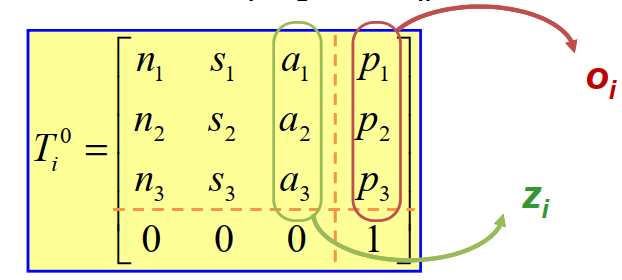

So, Jv and Jw can be easily calculated using the following equations:

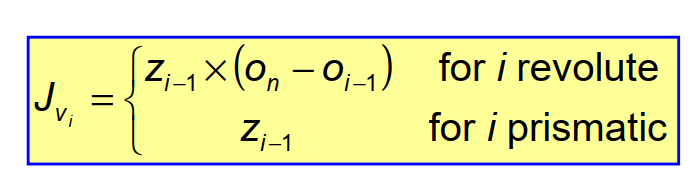    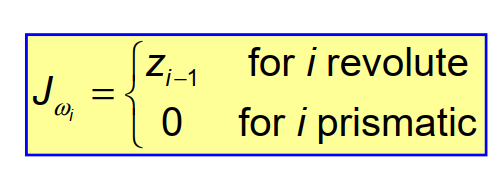

All parameters of Jacobian matrix are obtained

Jv1=cross(z(:,1),(o(:,7)-o(:,1)))

Jv2=cross(z(:,2),(o(:,7)-o(:,2)))

Jv3=cross(z(:,3),(o(:,7)-o(:,3)))

Jv4=cross(z(:,4),(o(:,7)-o(:,4)))

Jv5=cross(z(:,5),(o(:,7)-o(:,5)))

Jv6=cross(z(:,6),(o(:,7)-o(:,6)))

Jw1=z(:,1)

$$Jw1 = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

Jw2=z(:,2)

$$Jw2 = \left(\begin{array}{c} \sin\left(\theta_{1}\right)\\ -\cos\left(\theta_{1}\right)\\ 0 \end{array}\right)$$

Jw3=z(:,3)

$$Jw3 = \left(\begin{array}{c} -\sin\left(\theta_{1}\right)\\ \cos\left(\theta_{1}\right)\\ 0 \end{array}\right)$$

Jw4=z(:,4)

$$Jw4 = \left(\begin{array}{c} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\\ \cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)\\ -\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) \end{array}\right)$$

Jw5=z(:,5)

$$Jw5 = \left(\begin{array}{c} \sin\left(\theta_{4}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\right)-\cos\left(\theta_{4}\right)\,\sin\left(\theta_{1}\right)\\ \cos\left(\theta_{1}\right)\,\cos\left(\theta_{4}\right)+\sin\left(\theta_{4}\right)\,\left(\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\right)\\ -\sin\left(\theta_{4}\right)\,\left(\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\right) \end{array}\right)$$

Jw6=z(:,6)

$$Jw6 = \left(\begin{array}{c} -\sin\left(\theta_{5}\right)\,\left(\sin\left(\theta_{1}\right)\,\sin\left(\theta_{4}\right)+\cos\left(\theta_{4}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\right)\right)-\cos\left(\theta_{5}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\right)\\ \sin\left(\theta_{5}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{4}\right)-\cos\left(\theta_{4}\right)\,\left(\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\right)\right)-\cos\left(\theta_{5}\right)\,\left(\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)\\ \cos\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right)\,\left(\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\right)-\cos\left(\theta_{5}\right)\,\left(\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)+\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\right) \end{array}\right)$$

At last, all elements of Jacobian matrix is combined in a one matrix called Jacobian Matrix

J=[Jv1, Jv2, Jv3, Jv4, Jv5 Jv6; Jw1, Jw2, Jw3, Jw4, Jw5 Jw6]

## b) Discuss the singularities for position and orientation kinematics. 

If rank(*J *) ≤ 6  the manuplator is singular. However, in a 6 DOF manuplator, it is not easy to observe the rank of the matrix. So, there is a way that is called "decoupling singularities". They can be seperated as arm and wrist singularities.


$$J=\left\lbrack J_{p\;} \;J_o \right\rbrack$$
  

$J_p$: Position part

$J_o$: Orientation part

$J_o =\left\lbrack \begin{array}{ccc}
z_3 x\left(o_6 -o_3 \right) & z_4 x\left(o_6 -o_4 \right) & z_5 x\left(o_6 -o_5 \right)\\
z_3  & z_4  & z_5 
\end{array}\right\rbrack$Normally, $o_3 =o_4 =o_5 =o_6 =o$ for the manuplators without offsets. In our situation, $J_o =J_{12}$and it is not equal to zero.


$$J=\left\lbrack \begin{array}{cc}
J_{11}  & J_{12} \\
J_{21}  & J_{22} 
\end{array}\right\rbrack$$


$J_{22} =\left\lbrack \begin{array}{ccc}
z_3  & z_4  & z_5 
\end{array}\right\rbrack$ To determine wrist singularities, $\det \left|J_{22} \right|$should be examined. 

J_22=[z(:,3) z(:,4) z(:,5)]

$$J\_22 = \left(\begin{array}{ccc} -\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & \sin\left(\theta_{4}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\right)-\cos\left(\theta_{4}\right)\,\sin\left(\theta_{1}\right)\\ \cos\left(\theta_{1}\right) & \cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{4}\right)+\sin\left(\theta_{4}\right)\,\left(\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\right)\\ 0 & -\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & -\sin\left(\theta_{4}\right)\,\left(\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\right) \end{array}\right)$$

rank(J_22) 

ans = 3

It can be seen that $J_{22} \;$has full rank, so there is no wrist singularity. It is also can be proven because in the rist there is 120mm offset in the 3rd joint.

J_11=[cross(z(:,1),(o(:,4)-o(:,1))) cross(z(:,2),(o(:,4)-o(:,2))) cross(z(:,3),(o(:,4)-o(:,3)))];
det(J_11);
det_j_11=simplify(det(J_11))

$$det\_j\_11 = \frac{27\,\sin\left(\theta_{2}\right)\,{\cos\left(\theta_{3}\right)}^{2}}{3125}-\frac{27\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\,\cos\left(\theta_{3}\right)}{3125}-\frac{27\,\sin\left(\theta_{2}\right)}{3125}-\frac{81\,\sin\left(\theta_{3}\right)}{6250}-\frac{27\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{625}$$

eqn=det_j_11==0;
arm_singularity=solve(eqn,theta);
arm_singularity.theta2

$$ans = \begin{array}{l} \left(\begin{array}{c} -\log\left(-\frac{3\,{\mathrm{e}}^{2\,\mathrm{i}}\,\sin\left(1\right)+\sigma_{1}}{\sigma_{2}}\right)\,\mathrm{i}\\ -\log\left(-\frac{3\,{\mathrm{e}}^{2\,\mathrm{i}}\,\sin\left(1\right)-\sigma_{1}}{\sigma_{2}}\right)\,\mathrm{i}\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{\frac{1}{2}\,\mathrm{i}}\,\sqrt{26\,{\mathrm{e}}^{\mathrm{i}}-5\,{\mathrm{e}}^{2\,\mathrm{i}}-52\,{\mathrm{e}}^{3\,\mathrm{i}}-5\,{\mathrm{e}}^{4\,\mathrm{i}}+26\,{\mathrm{e}}^{5\,\mathrm{i}}+5\,{\mathrm{e}}^{6\,\mathrm{i}}+9\,{\mathrm{e}}^{3\,\mathrm{i}}\,{\sin\left(1\right)}^{2}+5}\\ \sigma_{2}=5\,{\mathrm{e}}^{\mathrm{i}}\,\mathrm{i}-{\mathrm{e}}^{2\,\mathrm{i}}\,\mathrm{i}-5\,{\mathrm{e}}^{3\,\mathrm{i}}\,\mathrm{i}+\mathrm{i} \end{array}$$

arm_singularity.theta3

$$ans = \left(\begin{array}{c} 1\\ 1\\ 0 \end{array}\right)$$

So, it can be seen that there are 4 singularity cases however in real life $\theta_2$ should be a real number so, there is no sinuglarity for that joint and for $\theta_3 \;$, it is singular 57.3 degree or zero degrees which are not in the range of motion for this manuplator.

Our manuplator has offsets in its 3rd, 4th and 6th joints, it can also be seen in its DH table. As a result, this KUKA manuplator is not singular corresponding to its configurations and offsets are added in order to prevent singularity.

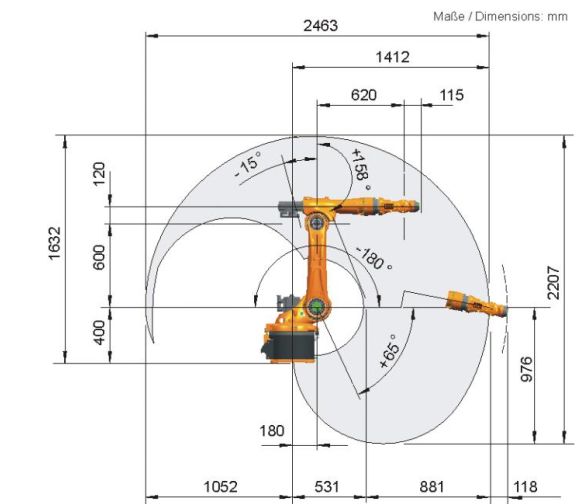  

det(J)==0